# Quantitative Methods for Finance

2025 Marina Dolfin

# **QMF2_2_Modelling_MonteCarloSimulations**

## Value at Risk Estimation via Monte Carlo Simulation of Return Distributions

**(A short theoretical background is provided at the end of the Live Script.)**

Value at Risk (VaR) measures the potential loss in portfolio value over a given time horizon and confidence level.

There are three main approaches to estimating VaR:

- **Parametric (Variance–Covariance)** — assumes normally distributed returns and computes VaR analytically from the mean and standard deviation.

- **Historical Simulation** — derives VaR directly from the empirical distribution of past returns, without distributional assumptions.

- **Monte Carlo Simulation** — generates many possible future return paths from a chosen stochastic model and evaluates VaR from the simulated distribution.

In this activity, we adopt the **Monte Carlo approach**, using simulated returns under a **Geometric Brownian Motion (GBM)** model to analyze the shape of future return distributions and assess **tail risk**.


clear all

close all

%% Download full daily history from Stooq
url = "https://stooq.com/q/d/l/?s=spy.us&i=d";
T = readtable(url);

writetable(T,'SPY.xlsx')

rng(123); %set the seed 


T.Date = datetime(T.Date, 'InputFormat','yyyy-MM-dd');
T = sortrows(T, "Date");


T = T(:, {'Date','Close'});
T.Properties.VariableNames{'Close'} = 'AdjClose';

%% Select samples
T_Q4 = T(T.Date >= datetime(2024,10,1) & ...
         T.Date <= datetime(2024,12,31), :);

T_Q1 = T(T.Date >= datetime(2025,1,1) & ...
         T.Date <= datetime(2025,3,31), :);

%% Sanity check
height(T_Q4)

ans = 64

height(T_Q1)

ans = 60

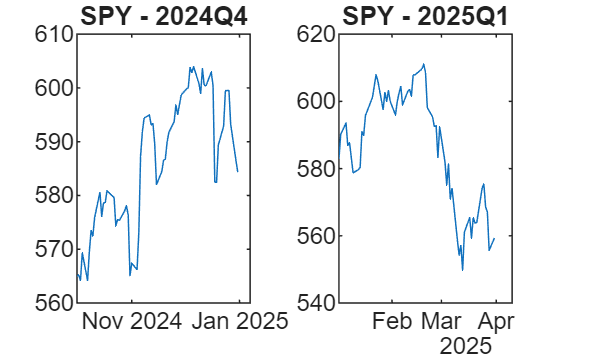


stock_Q4 =T_Q4.AdjClose;

stock_Q1=T_Q1.AdjClose;


subplot(1,2,1)
plot(T_Q4.Date,stock_Q4)
title('SPY - 2024Q4')

subplot(1,2,2)
plot(T_Q1.Date,stock_Q1)
title('SPY - 2025Q1')

#### Q4 2024 reflects political uncertainty without implementation, while Q1 2025 reflects early policy realization (notably trade-related), making a comparison of tail risk economically meaningful.

## Simulations

#### Set the parameters 

deltaT = 1;
numsim = 1000; %number of simulations

sim_days = 20; %set the parameter for how many days I'm projecting in the future

epsilon = randn(sim_days,numsim);


#### extract the value of the recorded last trading day of the stock of interest


S0_Q4 = stock_Q4(end)

S0_Q4 = 584.3230


S0_Q1 = stock_Q1(end)

S0_Q1 = 559.3900

#### Compute the logarithmic returns

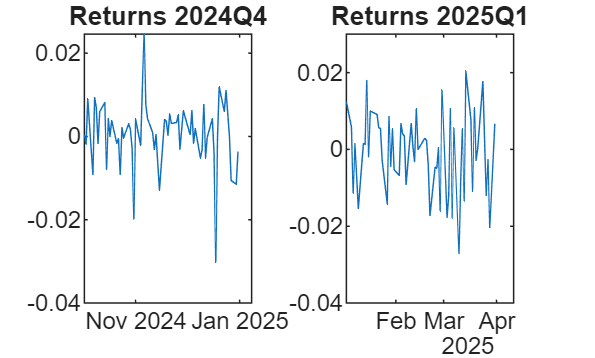



stockReturns_Q1 = diff(log(stock_Q1));

stockReturns_Q4 = diff(log(stock_Q4));

subplot(1,2,1)
plot(T_Q4.Date(2:end),stockReturns_Q4);

title('Returns 2024Q4')

subplot(1,2,2)
plot(T_Q1.Date(2:end),stockReturns_Q1);
ylim([-0.04,0.03])
title('Returns 2025Q1')

## *Which values of* μ *and* σ *make this model best match the observed data?*

##  Diagnostics (before calibrating GBM)

## 1) Stationarity (ADF on log-prices and returns)

## 2) Serial correlation (ACF / Ljung-Box)

## 3) Volatility clustering (ARCH test / ACF of squared returns)

## 4) Distribution (QQ plot / JB test)

## 5) Structural breaks (optional)

## 1)

## We test stationarity on log-prices to confirm the presence of a unit root and justify differencing, and then on log-returns to verify that the transformed series is stationary, as required for GBM calibration.

[h_pricesQ1,p_pricesQ1] = adftest(stockReturns_Q1)

h_pricesQ1 = logical
   1


p_pricesQ1 = 1.0000e-03


[h_pricesQ4,p_pricesQ4] = adftest(stockReturns_Q4)

h_pricesQ4 = logical
   1


p_pricesQ4 = 1.0000e-03

For log prices:

- **Fail to reject** the null hypothesis of a unit root

- Log-prices are **non-stationary**

- Consistent with a **random walk with drift**

- **Differencing is justified**


[h_returnsQ1,p_returnsQ1] = adftest(stockReturns_Q1)

h_returnsQ1 = logical
   1


p_returnsQ1 = 1.0000e-03


[h_returnsQ4,p_returnsQ4] = adftest(stockReturns_Q4)

h_returnsQ4 = logical
   1


p_returnsQ4 = 1.0000e-03

**For log returns:**

- **Reject** the unit root null

- Log-returns are **stationary**

- Mean and variance are stable over time

-  Calibration of a single μ and σ is statistically meaningful

## 2)

## We test for serial correlation to check whether **returns are independent over time**, as required by the GBM and by the way we simulate future paths.

h_Q1 = lbqtest(stockReturns_Q1)  %by default 20 lags are included

h_Q1 = logical
   0



h_Q4 = lbqtest(stockReturns_Q1)

h_Q4 = logical
   0


The Ljung–Box test fails to reject the null of no serial correlation in returns, supporting the assumption of independent innovations required by the GBM and Monte Carlo simulation.

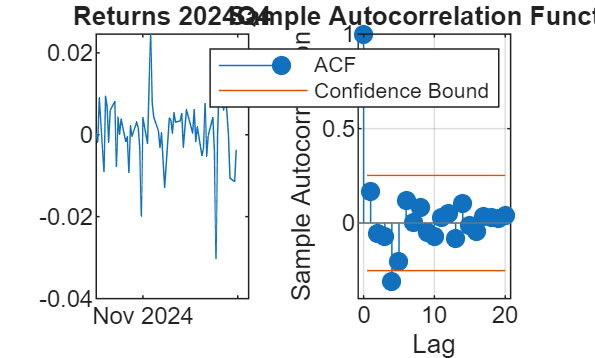

autocorr(stockReturns_Q1)

autocorr(stockReturns_Q4)

## 3)

## We test for volatility clustering to verify whether a *single, constant* σ is a valid description of risk over time.

h = archtest(stockReturns_Q1)

h = logical
   0



h = archtest(stockReturns_Q4)

h = logical
   0



autocorr(stockReturns_Q1.^2)

autocorr(stockReturns_Q4.^2)


The ARCH test fails to reject the null of no conditional heteroskedasticity in both samples, so we do not find statistical evidence of volatility clustering; therefore a constant-volatility GBM is a reasonable simplifying assumption for this exercise.

## 4)

## QQ plots and the JB test are primarily used to detect **departures from normality**, and in financial returns this typically manifests as **fat tails**, which imply that normal-based GBM VaR may underestimate extreme losses.

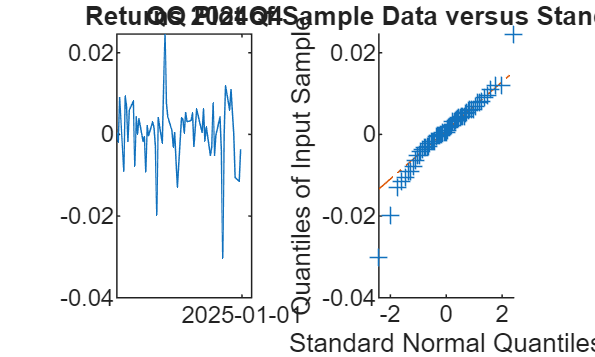


qqplot(stockReturns_Q1)  
qqplot(stockReturns_Q4)  %QQ plot against the normal distribution



% Jarque–Bera normality test
jbtest(stockReturns_Q1)

ans = 0


jbtest(stockReturns_Q4)

ans = 1

The QQ plot for Q1 2025 shows mild deviations in the tails, suggesting weak fat-tail behavior, while the Gaussian approximation remains reasonable for most observations.

The QQ plot for Q4 2024 exhibits stronger tail deviations, particularly in the lower tail, indicating heavier tails and potential downside risk relative to the normal distribution.

Normality appears to be a better approximation in Q1 2025 than in Q4 2024, although tail deviations are present in both samples.

The QQ plots indicate that returns are approximately normally distributed in the central region, but exhibit deviations in the tails, particularly in Q4 2024 where downside tail risk appears more pronounced. This suggests the presence of mild fat-tail behavior, implying that normal-based GBM VaR may underestimate extreme losses, especially at high confidence levels.

Consistently, the Jarque–Bera test rejects normality for Q4 2024 but fails to reject it for Q1 2025, suggesting that fat tails are statistically relevant in the former period but less so in the latter.

#### 5)

#### Structural break tests are performed when there is economic or visual evidence that the parameters of the return process may have changed; in their absence, a single-regime model is preferred for parsimony (optional).




mu_Q4 = mean(stockReturns_Q4)

mu_Q4 = 5.3339e-04


mu_Q1 = mean(stockReturns_Q1)

mu_Q1 = -6.9740e-04


sigma_Q4 = std(stockReturns_Q4)

sigma_Q4 = 0.0079


sigma_Q1 = std(stockReturns_Q1)

sigma_Q1 = 0.0104

#### Evaluate the stochastic factors

# 
$$e^{\Big(\mu-\frac{\sigma^2}{2}\Big)\Delta t+\epsilon\sigma\sqrt{\Delta t}}$$





factor_Q4 = exp((mu_Q4-sigma_Q4^2/2)*deltaT + sigma_Q4*epsilon*sqrt(deltaT));

factor_Q1 = exp((mu_Q1-sigma_Q1^2/2)*deltaT + sigma_Q1*epsilon*sqrt(deltaT));

#### Now, we can multiply each factor by the stock price of the given day (starting from the last trading day) to create the path (a realization of the stochastic process).

#### Concatenate vertically the last price to the vector of stochastic factors



factor_Q4 = [S0_Q4*ones(1,numsim);factor_Q4];

factor_Q1 = [S0_Q1*ones(1,numsim);factor_Q1];

## calculate the cumulative product using the vector of factors which was concatenated with the value of the last trading day


path_Q4 = cumprod(factor_Q4);

path_Q1 = cumprod(factor_Q1);


#### Now we have simulated the closing prices of the stock for the chosen number of future days after the last recorded price

#### The path is stored as a colum vector that can be plotted

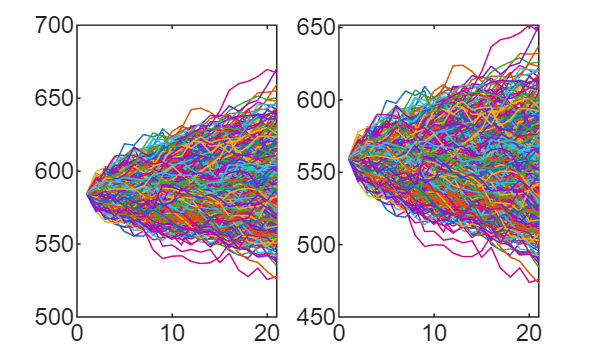

subplot(1,2,1)
plot(path_Q4)

subplot(1,2,2)
plot(path_Q1)

## Evaluate VaR of simulated prices

#### Extract the simulated final prices

finalPrices_Q4 = path_Q4(end,:);

finalPrices_Q1 = path_Q1(end,:);

Calculate the log returns of each path over the simulated days by subtracting the log of the initial price (S0) from the log of the final prices. 

Store the returns vector

 

possibleReturns_Q4 = log(finalPrices_Q4)-log(S0_Q4);

possibleReturns_Q1 = log(finalPrices_Q1)-log(S0_Q1);


plot the histogram of returns with a given number of bins

subplot(1,2,1)
histogram(possibleReturns_Q4,20)


 Calculate the 5% VaR, i.e. the fifth percentile of the possible returns (the function prctile(v,p) calculate the p percentile of the values in the vector v

 
var5_Q4 = -prctile(possibleReturns_Q4,1)

var5_Q4 = 0.0716



hold on


visualize VaR by plotting a red colored line representing 5 percent Value at Risk on top of the histogram


plot([-var5_Q4 -var5_Q4],[0 150],'r')
title('Simulated Returns—2024Q4')
hold off


subplot(1,2,2)
histogram(possibleReturns_Q1,20)


 Calculate the 5% VaR, i.e. the fifth percentile of the possible returns (the function prctile(v,p) calculate the p percentile of the values in the vector v

 
var5_Q1 = -prctile(possibleReturns_Q1,1)

var5_Q1 = 0.1224



hold on


visualize VaR by plotting a red colored line representing 5 percent Value at Risk on top of the histogram

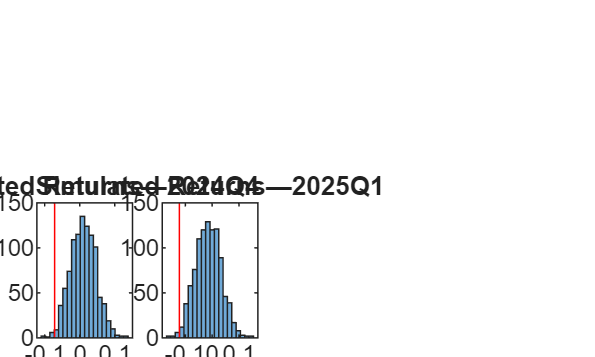


plot([-var5_Q1 -var5_Q1],[0 150],'r')
title('Simulated Returns—2025Q1')
hold off



% --- Convert return-VaR (log) to monetary VaR (per 1 share) ---
VaR_money_Q4 = S0_Q4 * (1 - exp(-var5_Q4))   % dollars (or same currency as S0), per share

VaR_money_Q4 = 40.3829


VaR_money_Q1 = S0_Q1 * (1 - exp(-var5_Q1))

VaR_money_Q1 = 64.4269


V0=1000 %nominal, as an example

V0 = 1000


VaR_money_Q4 = V0 * (1 - exp(-var5_Q4))

VaR_money_Q4 = 69.1106


VaR_money_Q1 = V0 * (1 - exp(-var5_Q1))

VaR_money_Q1 = 115.1734

## When using the Value-at-Risk measure, we are interested in making a statement of the following form:

## "We are X percent certain that we will not lose more than V pounds in time T"

## The variable V is the VaR of the portfolio. It is a function of two parameters: the time horizon T and the confidence level X percent. 

## It is the loss level during a time period of length T that we are X% certain will not be exceeded.

## For example, when T is five days and X=97, VaR is the loss at the 3rd percentile of the distribution of gains over the next five days. 

## Alternatively, it is the loss at the 97th percentile of the distribution of losses over the next five days.  More generally, when the distribution of gains is used, VaR is equal to minus the gain at the (100-X)th percentile of the distribution.

## 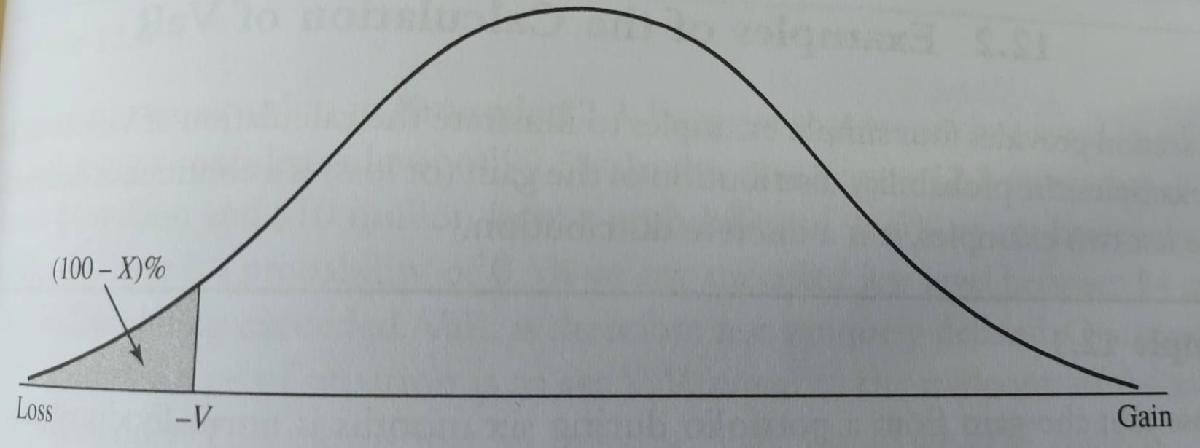

## Example

## Suppose that the gain from a portfolio during six months is normally distributed with a mean of £2 m and a standard deviation of £10 m. The 1-percentile point of the normal distribution is

## 
$$\textsterling 2 m-2.326*\textsterling 10 m = - \textsterling 21.3 m$$


## VaR = norminv(0.01,2,10)

## VaR is an attractive measure, because it is easy to understand. 

## It asks the simple question "How bad can things get?" 

## However, when VaR is used in an attempt to limit the risks taken by a trader, it can lead to undesiderable results. 

## Suppose that a bank tells a trader that the one-day 99% VaR of the trader's portfolio must be limited to £10 m. The trader can contruct a portfolio where there is a 99.1% chance that the daily loss is less then £10 m, and a 0.9% chance that is £500 m. 

## The trader is satysfying the risk limits imposed by the bank, but is clearly taking unacceptable risks. 

## 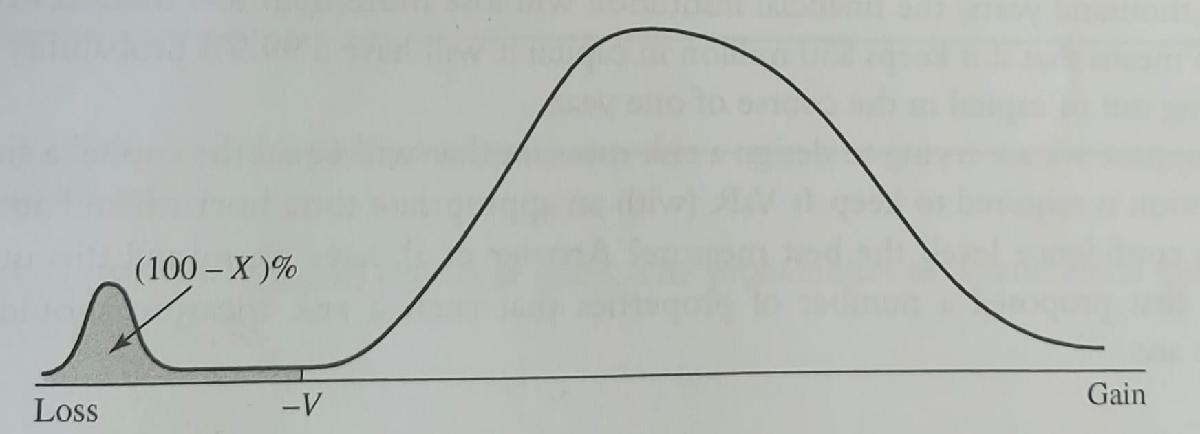

## Even if the two Var for the two distributions are the same, of course the portfolio related to the second distribution is much riskier the the first one.

## It should moreover be noticed that a probability distribution like the one above is not that unusual as one might think.

## Modelling uncertainty

## We assume that a variable, say the price of a stock or a commodity, can be modelled as a random variable, whose probability distribution is known, possibly inferred from available data (we are using only exogeneous uncertainty). 

## The simplest model of uncertainty is the binomial model. 

## We know the current price $S_0$ at time t=0, and we assume that the price $S_1$, at some future time instant t=1, can take only two values.

## 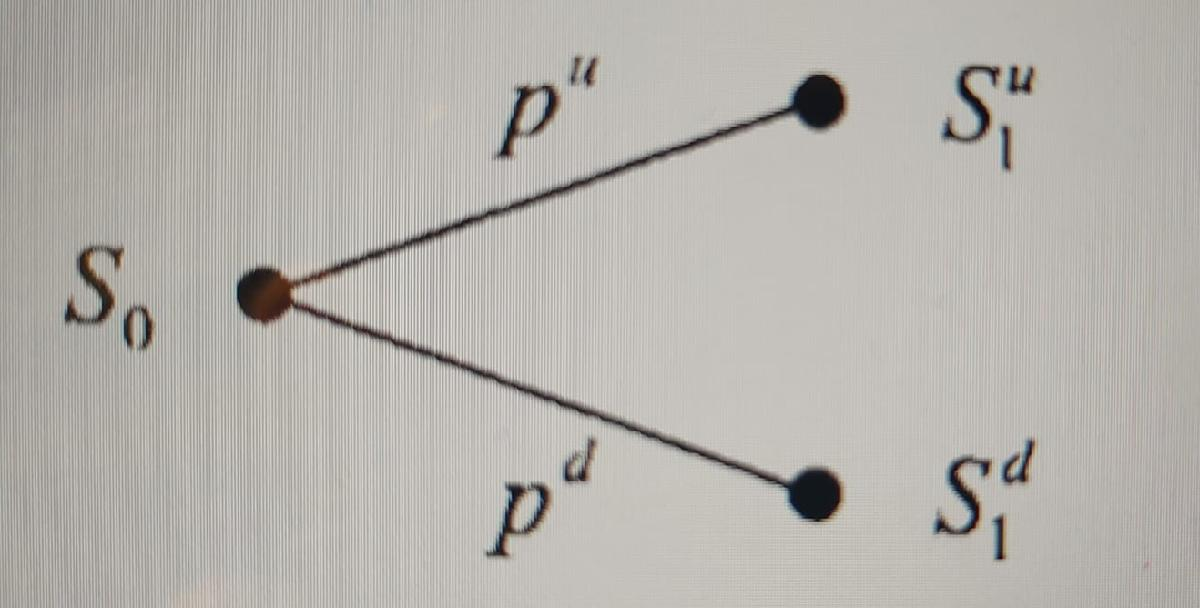

## A common choice is to represent uncertainty by a multiplicative shock, i.e. $S_1^u=uS_0$ and $S_1^d=dS_0$, where the letters u and d suggest 'up' and 'down', respectively (hence, d<u). 

## Apparently, this model is very crude, but it is the building block of very useful models.

## A more refined model can be built by allowing for more then just two future states. 

##  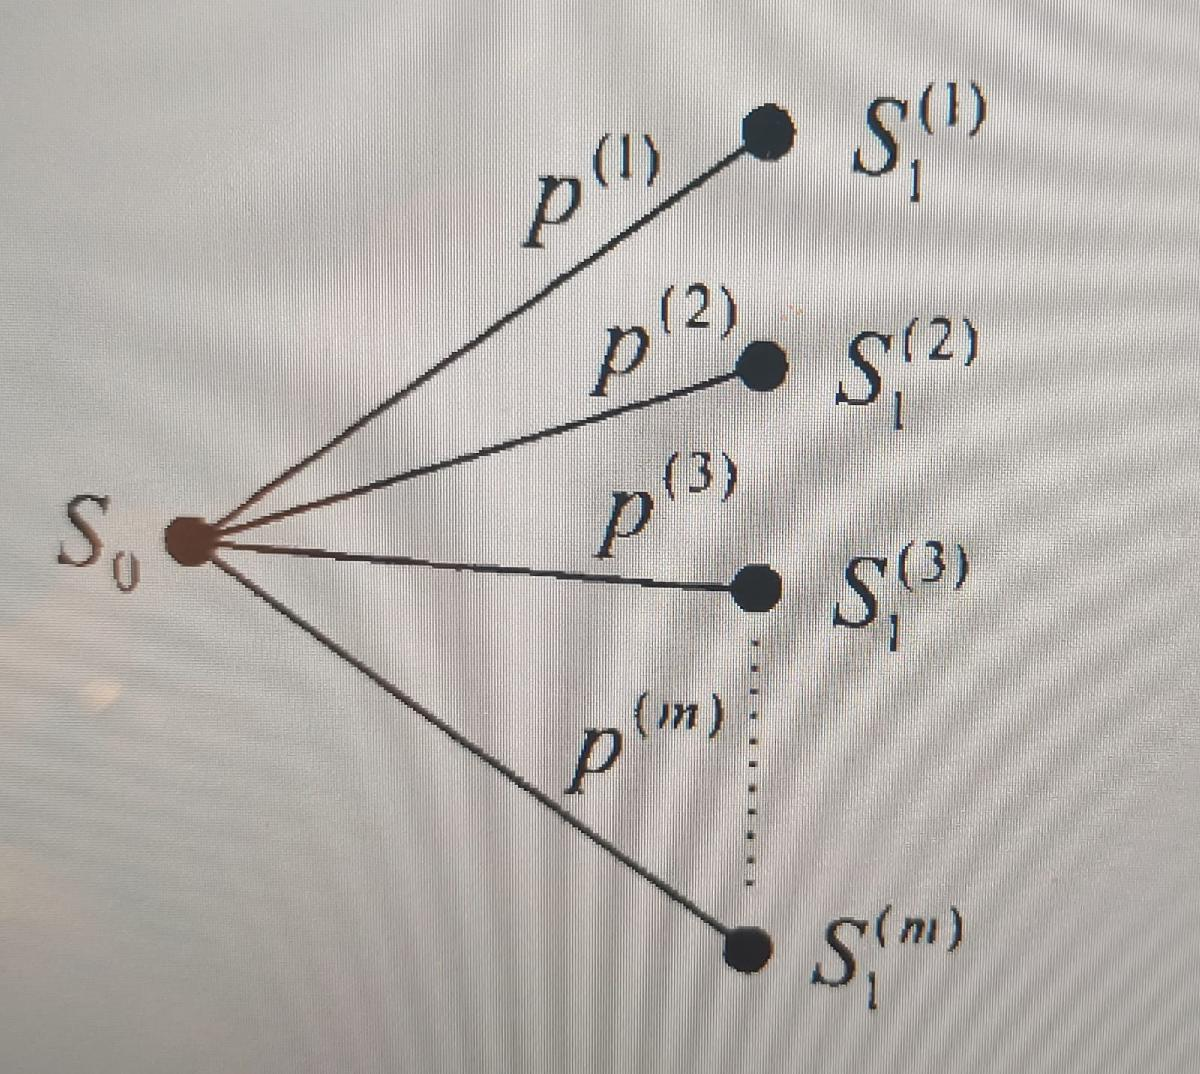

## Moreover, one can consider a discrete-state, discrete-time, multiperiod model

## 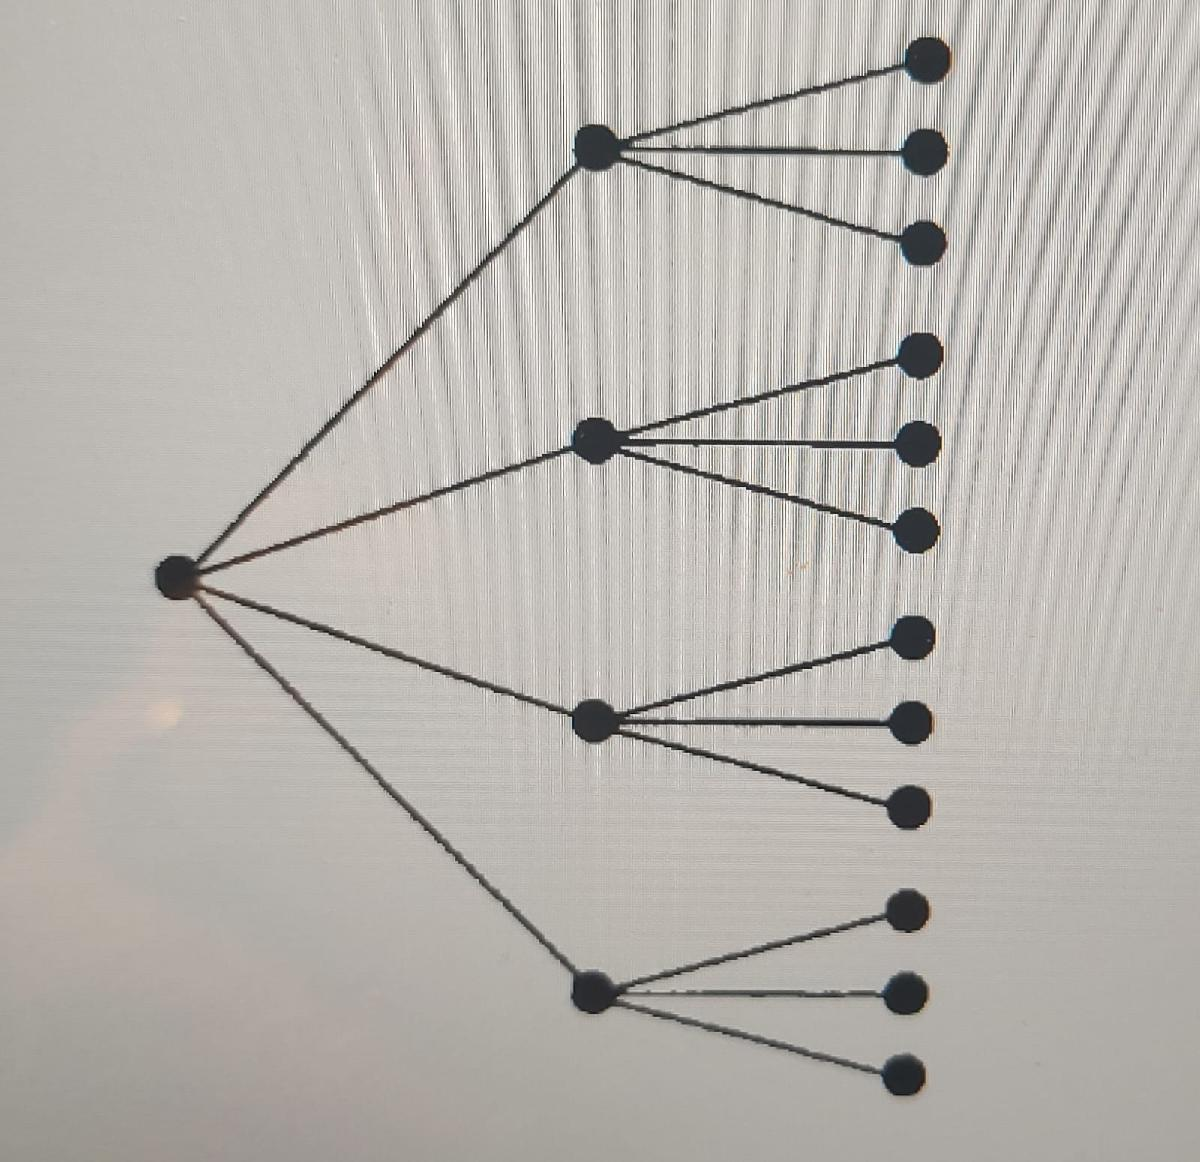

## Sometimes, to keep computational effort limited, we prefer using a recombining lattice.

## 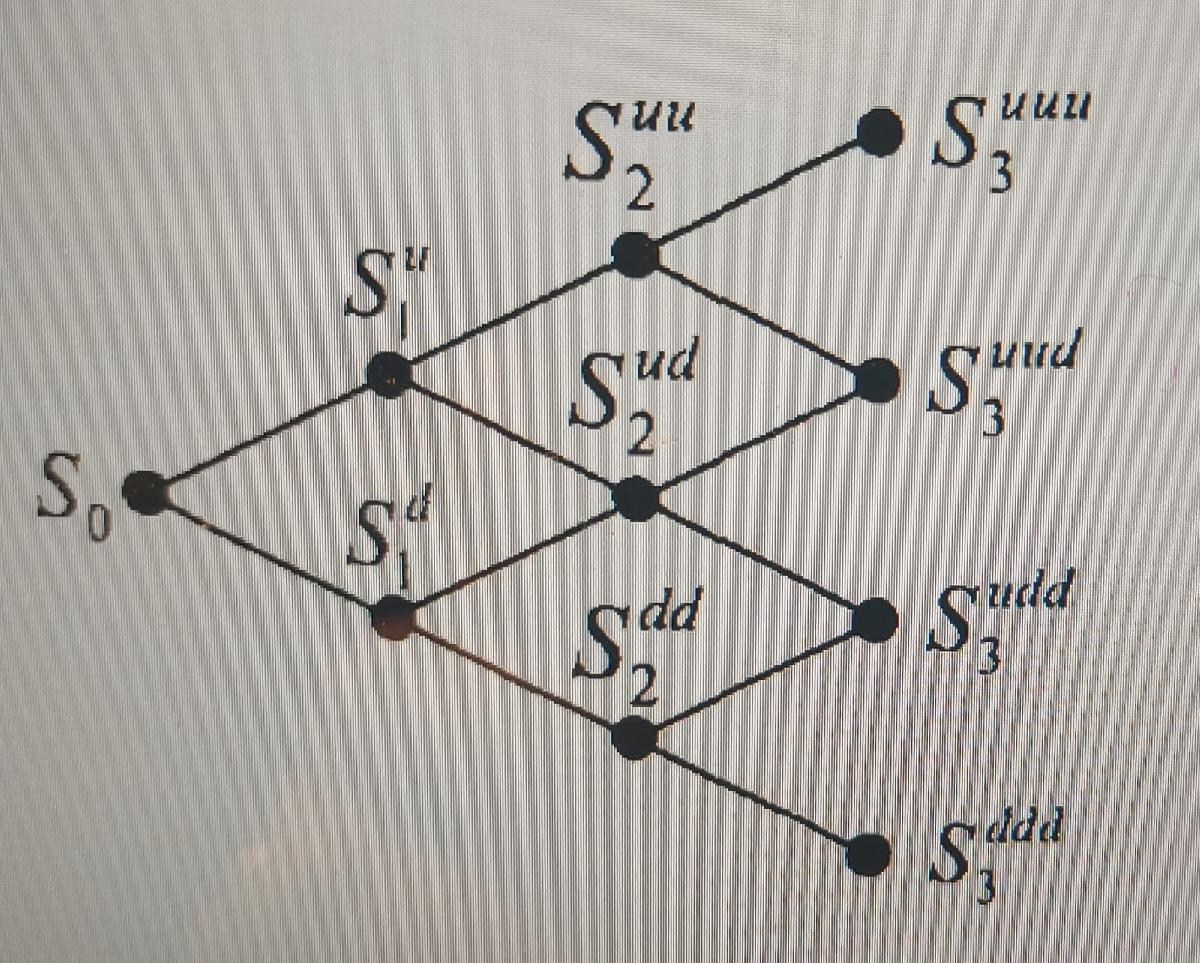

## Since $udS_0=duS_0$, we see that an up-jump followed by a down-jump is the same as a down-jump followed by an up-jump. 

## This means also assuming that the multiplicative shocks are always the same, which makes sense if the process is stationary and time step is constant.

## Sometimes, it is convenient to model uncertainty using instead a continuous distribution, such as the normal. 

## If we think of prices, a continuous distribution is certainly an idealization, since no price is quoted with too many decimal digits. 

## By the same token, we may also resort to continuous-time models, which may be thought of as the limit of a discrete-time model when the time step tends to zero.

## In this case, the usual building block is the Wiener process W(t), that can be considered as the continuous-time limit of a random walk described by a binomial lattice. 

## Geometric Brownian Motion (GBM)

## The standard Wiener process is a useful building block, but it cannot be directly used to model stock prices or interest rates, since (among other issues) it may take negative values. 

## To that aim, we introduce a powerful modelling framework to describe continuous - state, continuous-time processes. Informally, we talk about stochastic differential equations. 

## If we want to write a stochastic differential equation modelling the random return of an asset, we might consider the following modification of the generalized Wiener process:

## 
$$\frac{d S(t)}{S(t)}=\mu dt+\sigma dW(t)$$


## One can think then to that as the differential of log-price, $d\,log\,S_t$ and integrate it directly

## 
$$log\, S(t) -log\,S(0) =\Big( \mu-\frac{\sigma^2}{2}\Big)t+\sigma W(t)$$


## By recalling that $W_t$ has a normal distribution and can be written as $W_t =\epsilon\sqrt t$ with $\epsilon\sim N(0,1)$, we can rewrite the solution in terms of $S_t$ as

## 
$$S(t)=S(0)e^{\Big(\mu-\frac{\sigma^2}{2}\Big)t+\epsilon\sigma\sqrt{t}\Big)$$


## On the one hand, this shows that prices, according to the Geometric Brownian motion model, are log-normally distributed and cannot take negative values.

## On the other hand, now we have a way to generate sample paths, based on a discretization of a prescribed time horizon into time periods of length $\Delta t$.

## A brief note: relation with option pricing. Consider a vanilla option like a European-style call option written on a nondividend paying stock, whose price S(t) follows a geometric Brownian motion. Since increments in the driving Wiener process are independent, we may say that future history does not depend on the past. And we may also show that the value of the option at a time t before maturity will depend only on time (more precisely, time to maturity) and current price of the underlying.

## This leads to the Black-Scholes model (but this is another story...).

## Discretization and Monte Carlo approach

## When discretizing time, you simulate the stock price at time $t+\Delta t$ (tomorrow) by 

## 
$$S(t+\Delta t)=S(t)e^{\Big(\mu-\frac{\sigma^2}{2}\Big)\Delta t+\epsilon\sigma\sqrt{\Delta t}\Big)$$


## where

## $\mu$ mean return

## $\sigma$standard deviation of returns

## $\epsilon$ random variable

## The above formula generates sample paths.

## Note on simple vs log returns

When simulating price dynamics, two related but distinct measures of returns are commonly used: **simple returns** and **logarithmic (log) returns**.

The simple return measures the percentage change in price between two periods, while the log return is the natural logarithm of the price ratio.

For small price movements, they are numerically close, but log returns are additive over time and follow a Normal distribution under the **Geometric Brownian Motion (GBM)** model.

For this reason, GBM simulations are typically generated in terms of log returns.

In contrast, **Value at Risk (VaR)** is often reported in terms of *simple returns* or *monetary losses*, because these are easier to interpret.

Once the simulated log returns are obtained, they can be converted to simple returns to express losses as percentages or absolute amounts.

For example, if the 5th percentile of simulated log returns is –0.05, the equivalent simple return is e−0.05−1≈−4.88%e^{-0.05} - 1 \approx -4.88\%e−0.05−1≈−4.88%.

If the current portfolio value is $100,000, this corresponds to a 95% VaR of $4,880.

## References:

## [1] Glasserman, P. Monte Carlo Methods in Financial Engineering. Springer-Verlag, New York, 2004.

## [2] Hull, J. C. Options, Futures, and Other Derivatives. 5th edition, Englewood Cliffs, NJ: Prentice Hall, 2002